# Arraging our data to Slam enviroment

Before start run the MR_support.mlx at  ....../MatlabDrive/Robotica_20_21_2Q/11_Localization

Slam need thinghs at origen


T_B_A=transl(8.65,17.2,0)*trotz(-pi/2)

T_B_A =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


T_A_B=trotz(pi/2)*transl(-8.65,-17.2,0)% or inv(T_B_A)

T_A_B =          0   -1.0000         0   17.2000
    1.0000         0         0   -8.6500
         0         0    1.0000         0
         0         0         0    1.0000



Pose_t_0=T_A_B*[Pose_t.Data(:,1:2) zeros(length(Pose_t.Data),1),ones(length(Pose_t.Data),1)]'%...

Pose_t_0 =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0008    0.0016    0.0025    0.0041    0.0057    0.0074    0.0082    0.0098    0.0116    0.0134    0.0158    0.0187    0.0215    0.0247    0.0280    0.0312    0.0348    0.0387    0.0428    0.0472    0.0517    0.0561    0.0605    0.0651    0.0697    0.0748    0.0800    0.0849    0.0898    0.0950    0.1003    0.1060    0.1116    0.1171    0.1227    0.1285    0.1345
         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009   -0.0009   -0.0010   -0.00


Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];


Lmk= T_A_B*Lmk'

Lmk =     0.7690    0.7690    3.7560    6.7390    6.6660    9.6530   10.5460   10.6750    9.0640
   -0.7160    0.9330    0.9340    0.9340   -0.6770   -0.7160    0.9340    4.3510    8.3570
         0         0         0         0         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


lmk=Lmk(1:2,:) % The function ekfslam_sim.m need it as 2xN Landmarks

lmk =     0.7690    0.7690    3.7560    6.7390    6.6660    9.6530   10.5460   10.6750    9.0640
   -0.7160    0.9330    0.9340    0.9340   -0.6770   -0.7160    0.9340    4.3510    8.3570


Plot our data at origen

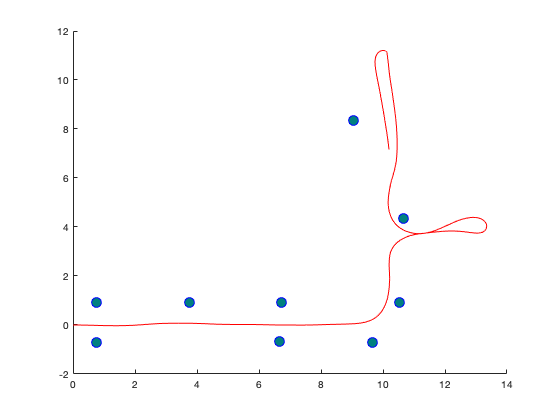

figure
sz = 100;
s=scatter(Lmk(1,:),Lmk(2,:),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];
hold on
plot(Pose_t_0(1,:),Pose_t_0(2,:),'r')

Get way_point to drive the Robot

Remember the Go to point Architecture / algorithm

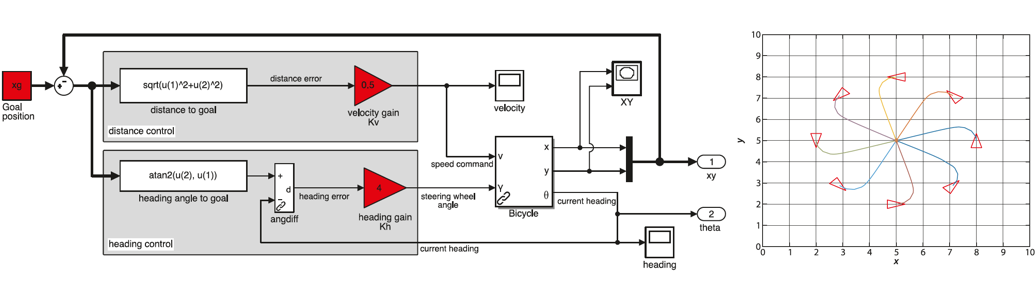

We subsample our theoric trajectory

len=length(Pose_t_0);
j=0

j = 0

for i=1:len   
k=mod(i,50) % every L samples
if k==0 
j=1+j
way_points(:,j)=Pose_t_0(1:2,i)  
end
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 1

way_points =     0.1345
   -0.0011


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 2

way_points =     0.1345    0.5481
   -0.0011   -0.0094


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 3

way_points =     0.1345    0.5481    1.0918
   -0.0011   -0.0094   -0.0261


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 4

way_points =     0.1345    0.5481    1.0918    1.6516
   -0.0011   -0.0094   -0.0261   -0.0248


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 5

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 6

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 7

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 8

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 9

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 10

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 11

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 12

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 13

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 14

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 15

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 16

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 17

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 18

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 19

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 20

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 21

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 22

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 23

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 24

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 25

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 26

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 27

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 28

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 29

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 30

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 31

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 32

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 33

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 34

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730   11.0948
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549    3.7312


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 35

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730   11.0948   10.5651
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549    3.7312    3.9481


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 36

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730   11.0948   10.5651   10.2344
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549    3.7312    3.9481    4.4944


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 37

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730   11.0948   10.5651   10.2344   10.1706
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549    3.7312    3.9481    4.4944    5.1522


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 0

j = 38

way_points =     0.1345    0.5481    1.0918    1.6516    2.2223    2.8683    3.4950    4.1523    4.8987    5.6635    6.3692    7.0802    7.8010    8.4689    9.1145    9.6212    9.9301   10.1327   10.2092   10.1990   10.2485   10.5120   11.0532   11.6977   12.3298   12.8426   13.1388   13.2934   13.3370   13.1420   12.7203   12.2177   11.6730   11.0948   10.5651   10.2344   10.1706   10.2521
   -0.0011   -0.0094   -0.0261   -0.0248    0.0115    0.0630    0.0731    0.0580    0.0260    0.0218    0.0062   -0.0021    0.0045    0.0282    0.0571    0.2023    0.5143    1.0378    1.7169    2.4207    2.9786    3.4225    3.6989    3.7978    3.8337    3.7700    3.7612    3.8603    4.0970    4.3423    4.3664    4.1523    3.8549    3.7312    3.9481    4.4944    5.1522    5.7875


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

Plot the way points

figure
plot(way_points(1,:),way_points(2,:),'r')

Save data

save('Pasillo_Omega.mat','lmk','way_points')

Run the simulation

In the file 'config.m' play witt the parameteres

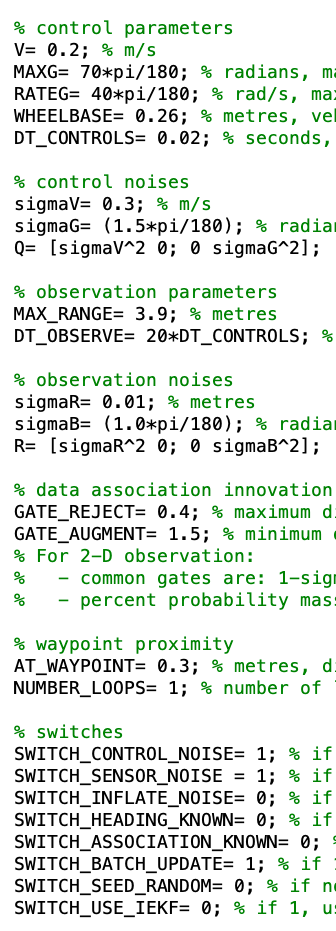

load('Pasillo_Omega.mat')
ekfslam_sim(lmk,way_points)
plot_feature_loci(ans)